# Calculating the Fourier Series of a Square Wave 

In this MATLAB live script, we will plot a square wave and its approximated Fourier series over the interval [-pi, pi].

First, clear any previously-assigned variables.

clear

## 1. Defining the square wave f(t) in the first period

The function that we want to approximate is a kind of top hat between -pi/2 and pi/2.

Let's define in it MATLAB using **heaviside step functions **as there are multiple kinds of behaviour (zero and 17) within the first period -pi<t<pi:

syms t
f = 17 * (heaviside(t + pi/2) - heaviside(t - pi/2))

$$f = 17\,\mathrm{heaviside}\left(t+\frac{\pi }{2}\right)-17\,\mathrm{heaviside}\left(t-\frac{\pi }{2}\right)$$

Let's plot it and see what we are aiming for:

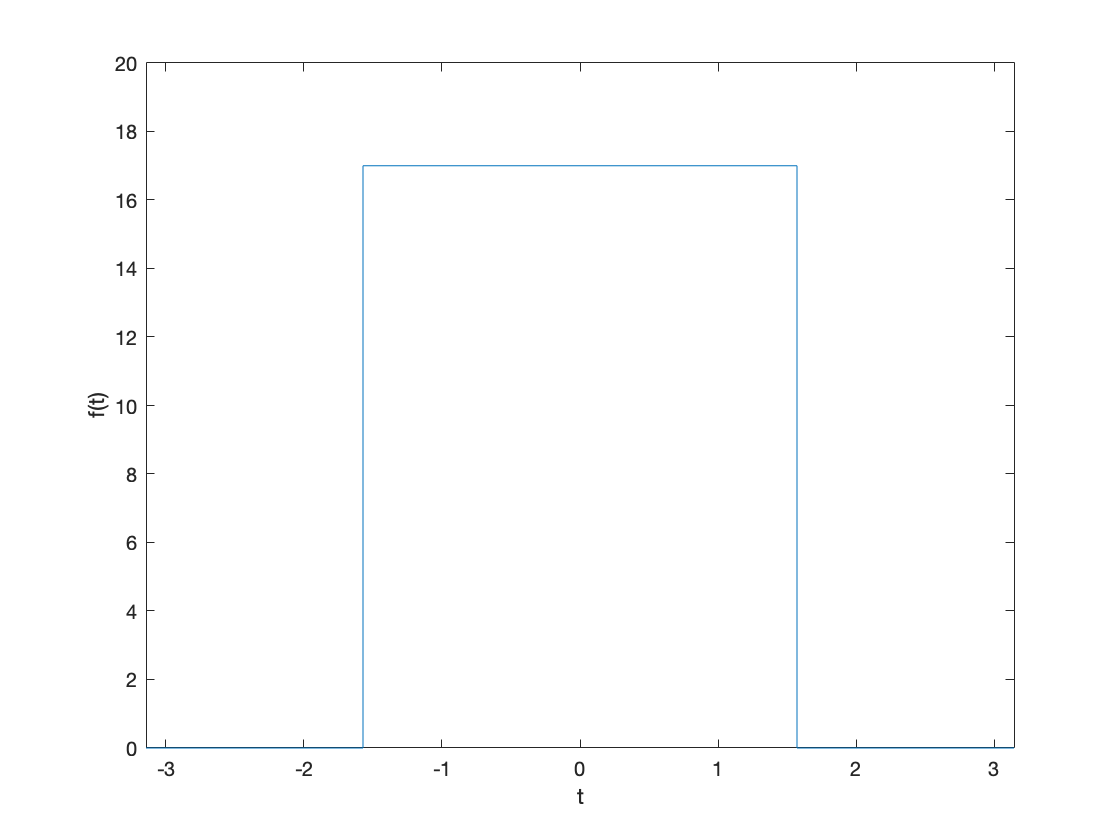

fplot(f, [-pi, pi])
ylim([0 20]) % change the y-axis on display
xlabel('t')
ylabel('f(t)')

## 2. Calculating the first few Fourier coefficients

Next, let's define some key features. The period is 2pi, and then we also will need the angular frequency:

T = 2*pi        % this is dependent on the graph of this specific wave

T = 6.2832

w = 2*pi/T      % this relationship is ALWAYS true by definition

w = 1

Then, we want to calculate the a_k coefficients (including a_0). Normally we would integrate over the range [0 T] (in this case [0 2pi]). However, as we have defined the function from -pi < t < pi, we need to integrate over that region instead:

a0 = int(f, t, -pi, pi)*2/T

$$a0 = 17$$


a1 = int(f * cos(w*t), t, -pi, pi)*2/T

$$a1 = \frac{34}{\pi }$$


a2 = int(f * cos(2 * w * t), t, -pi, pi)*2/T

$$a2 = 0$$


a3 = int(f * cos(3 * w * t), t, -pi, pi)*2/T

$$a3 = -\frac{34}{3\,\pi }$$


a4 = int(f * cos(4 * w * t), t, -pi, pi)*2/T

$$a4 = 0$$


a5 = int(f * cos(5 * w * t), t, -pi, pi)*2/T

$$a5 = \frac{34}{5\,\pi }$$

Notice that every other one is zero.

Now, let's look at the b_k coefficients:

b1 = int(f * sin(w*t), t, -pi, pi)*2/T

$$b1 = 0$$


b2 = int(f * sin(2 * w * t), t, -pi, pi)*2/T

$$b2 = 0$$


b3 = int(f * sin(3 * w * t), t, -pi, pi)*2/T

$$b3 = 0$$

It turns out that all of the sin terms are zero. This is because this particular Square Wave above is **even**.

## 3. Plotting the approximate Fourier Series

Let's look how closely our series now matches the true function that we want.

Let's call the sum FourierApprox, as in "Fourier Approximation", as we don't have an infinite set of terms. This is also called the "5th partial sum".

FourierApprox = a0/2 + a1 * cos(w*t) + a2 * cos(2 * w* t) + a3 * cos(3 * w * t)...
                + a4 * cos(4 * w * t) + a5 * cos(5 * w * t)

$$FourierApprox = \frac{34\,\cos\left(5\,t\right)}{5\,\pi }-\frac{34\,\cos\left(3\,t\right)}{3\,\pi }+\frac{34\,\cos\left(t\right)}{\pi }+\frac{17}{2}$$

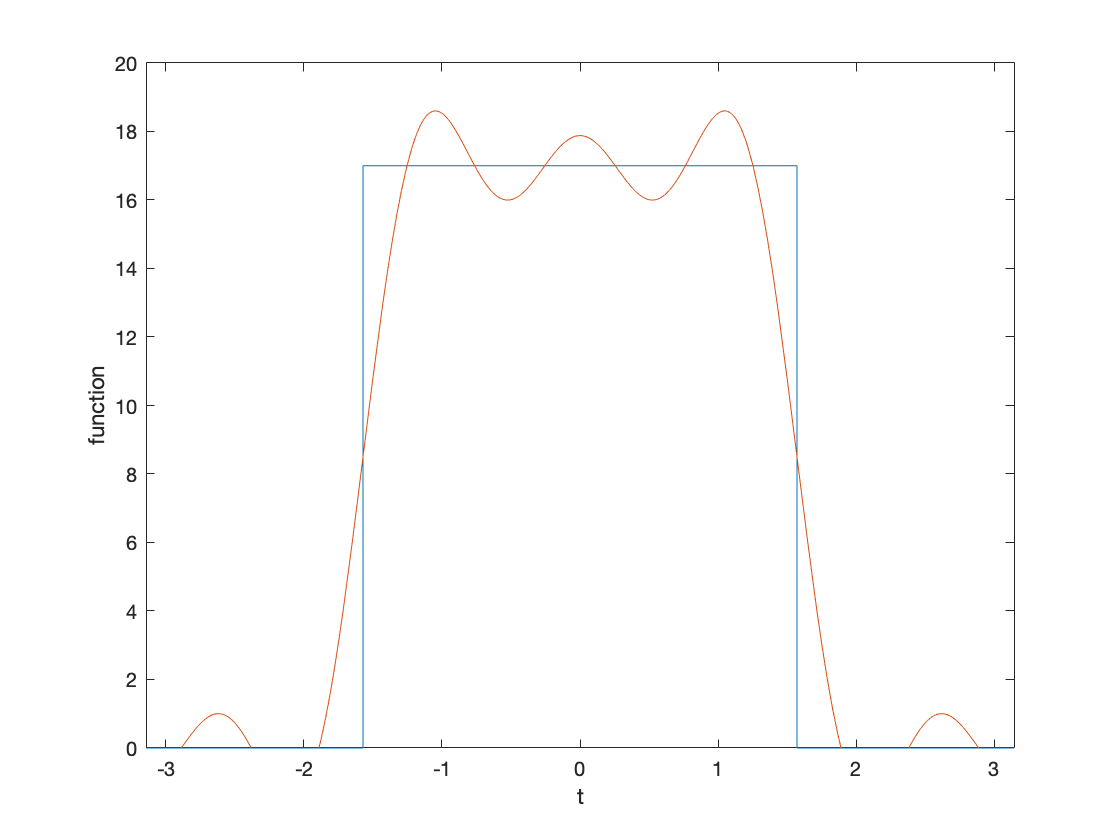

% Note that we have not included the sine terms as the b_k coefficients
% were all zero anyway.
fplot(f, [-pi, pi])
hold on % this allows us to plot the next function on the same graph
fplot(FourierApprox, [-pi, pi])
hold off
xlabel('t')
ylabel('function')
ylim([0 20]) 

It's starting to look something like the square wave, but it's not a great approximation.

For different functions, the Fourier series will converge to the function at different rates. Some functions require more coefficients that others to achieve a reasonable fit.

## 4. Calculating additional Fourier coefficients and plotting a more accurate approximation to the Fourier Series

Let's add another few terms on:

a6 = int(f * cos(6 * w * t), t, -pi, pi)*2/T

$$a6 = 0$$


a7 = int(f * cos(7 * w * t), t, -pi, pi)*2/T

$$a7 = -\frac{34}{7\,\pi }$$


a8 = int(f * cos(8 * w * t), t, -pi, pi)*2/T

$$a8 = 0$$


a9 = int(f * cos(9 * w * t), t, -pi, pi)*2/T

$$a9 = \frac{34}{9\,\pi }$$


% Create the new Fourier partial sum:
FourierApproxMore = a0/2 + a1 * cos(w*t) + a2 * cos(2 * w * t) + a3 * cos(3 * w * t)...
                    + a4 * cos(4 * w * t) + a5 * cos(5 * w * t) + a6 * cos(6 * w * t)...
                    + a7 * cos(7 * w * t) + a8 * cos(8 * w * t) + a9 * cos(9 * w * t)

$$FourierApproxMore = \frac{34\,\cos\left(5\,t\right)}{5\,\pi }-\frac{34\,\cos\left(3\,t\right)}{3\,\pi }-\frac{34\,\cos\left(7\,t\right)}{7\,\pi }+\frac{34\,\cos\left(9\,t\right)}{9\,\pi }+\frac{34\,\cos\left(t\right)}{\pi }+\frac{17}{2}$$

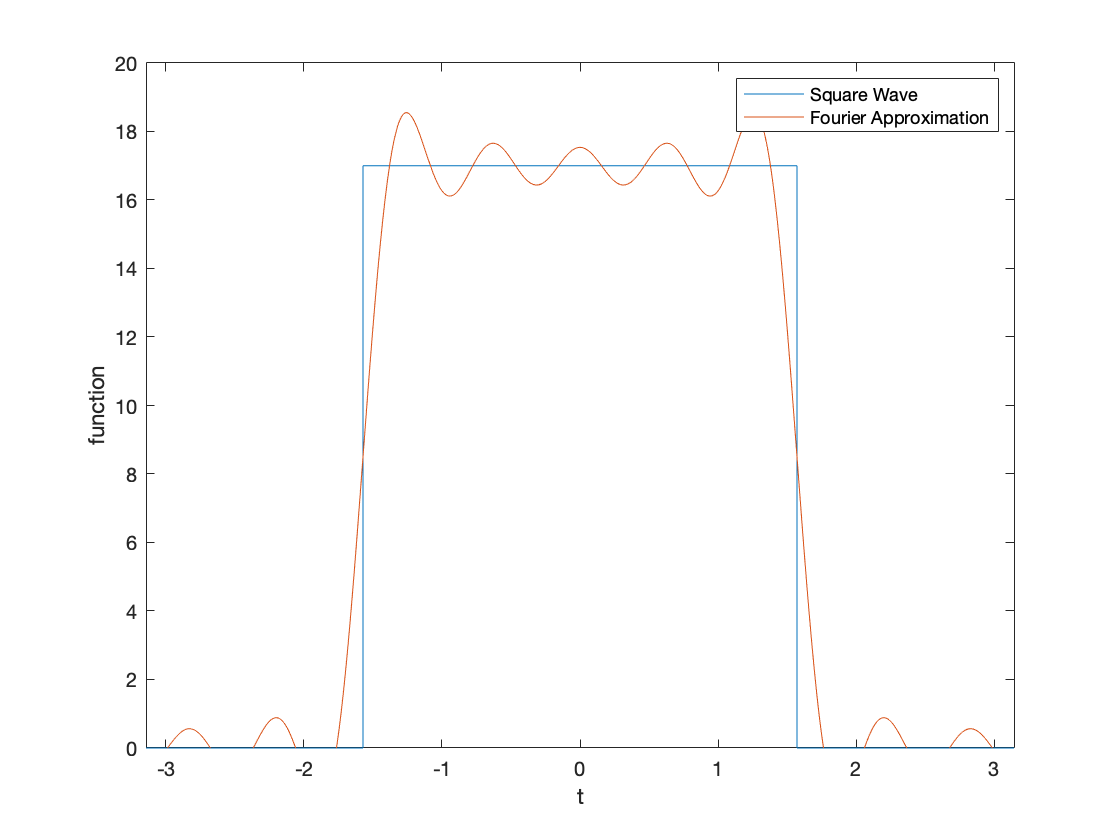


% Plot it and the square wave on the same graph:
fplot(f, [-pi, pi])
hold on
fplot(FourierApproxMore, [-pi, pi])
hold off
ylim([0 20])
xlabel('t')
ylabel('function')
legend('Square Wave', 'Fourier Approximation')

It's starting to look much more like the function we want.

If we keep adding terms we get closer and closer to the top hat shape of the true Square Wave.